clear
clc

% Параметры
Theta_total = 2720; % полный угол [град]
T_total = 4.1;        % общее время [с]
T_acc = 2.05;          % время разгона [с]
T_dec = 2.05;          % время торможения [с]
T_const = T_total - T_acc - T_dec; % участок с постоянной скоростью

% Макс ускорение через интеграл синусоида:
% Разгон по синусу:
% omega_max = 2*A_max*T_acc/pi
% путь на разгоне = A_max*T_acc^2/pi

A_max = Theta_total * pi / (2*T_acc^2 + 2*T_acc*T_const);
% Общий путь:
% Theta_total = 2*(A_max*T_acc^2/pi) + omega_max * T_const

% Выражаем A_max:
omega_max = 2*T_acc/pi; % относительный коэффициент
S_acc = (2/pi) * A_max * T_acc^2; % угол на разгон/торможение
S_const = omega_max * A_max * T_const;

% Уравнение баланса угла:
% Theta_total = 2*S_acc + S_const
% подставляем:
% Theta_total = 2*(A_max*T_acc^2/pi) + (2*A_max*T_acc/pi)*T_const

A_max = Theta_total / ( 2*(T_acc^2/pi) + 2*T_acc*T_const/pi );

% Время и инициализация
dt = 0.01;
t = 0:dt:T_total;
theta = zeros(size(t));
omega = zeros(size(t));
alpha = zeros(size(t));

for i = 2:length(t)
    ti = t(i);

    if ti <= T_acc
        % Разгон: ускорение по синусу
        alpha(i) = A_max * sin( pi * ti / T_acc );
    elseif ti <= T_acc + T_const
        % Постоянная скорость
        alpha(i) = 0;
    elseif ti <= T_acc + T_const + T_dec
        % Торможение: зеркально
        tau = ti - (T_acc + T_const);
        alpha(i) = -A_max * sin( pi * tau / T_dec );
    else
        alpha(i) = 0;
    end

    omega(i) = omega(i-1) + alpha(i) * dt;
    theta(i) = theta(i-1) + omega(i) * dt;
end
jerk = diff(alpha) / dt;            % jerk в точках между узлами
t_jerk = t(1:end-1) + dt/2;         % чтобы jerk "лежал" посередине шага

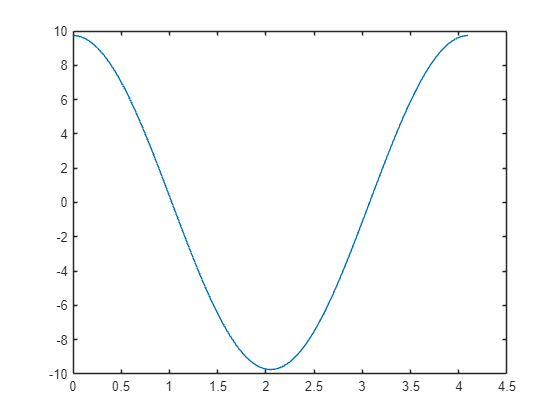

% Графики
figure
plot(t_jerk,jerk/160);

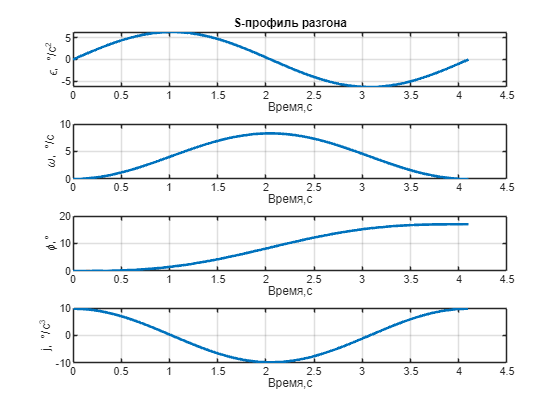


figure;
subplot(4,1,3); plot(t, theta/160, 'LineWidth',2); grid on; ylabel('\phi,°'); xlabel('Время,с');xlim([0 4.5]);
subplot(4,1,2); plot(t, omega/160,'LineWidth',2); grid on; ylabel('\omega, °/c');xlabel('Время,с');xlim([0 4.5]);
subplot(4,1,1); plot(t, alpha/160,'LineWidth',2); grid on; ylabel('\epsilon, °/c^2');title("S-профиль разгона");xlabel('Время,с');xlim([0 4.5])
subplot(4,1,4);plot(t_jerk, jerk/160, 'LineWidth',2);grid on; ylabel("j, °/c^3"); xlabel("Время,с");xlim([0 4.5]);
saveas(gcf, 'S-curve-sin.png');        % PNG

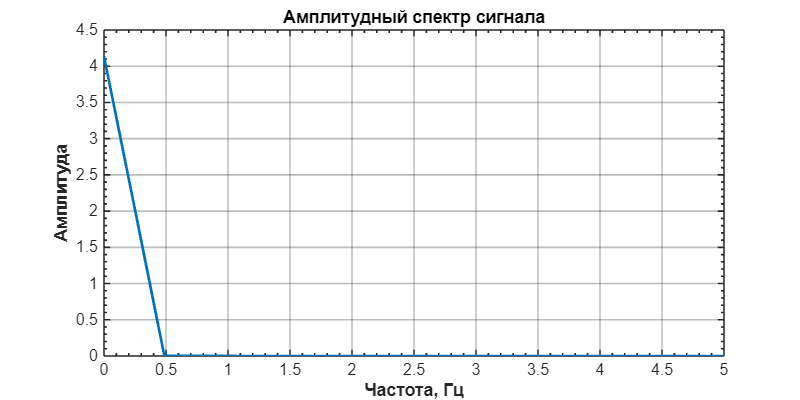

% Преобразование Фурье
Fs = 1/dt;
N = length(t);
f = (0:N-1)*(Fs/N);

fftAll = fft(omega/160);
amp = abs(fftAll)/N;


f_plot = f(1:floor(N/2));
amp_plot = amp(1:floor(N/2)); % <-- правильно
figure('Color','w', 'Position',[100 100 800 400]);  % белый фон и размер

plot(f_plot, amp_plot, 'LineWidth', 2);             % более жирная линия
xlim([0 5]);                                       % ограничение по частоте

grid on;

% Подписи осей
xlabel('Частота, Гц', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Амплитуда', 'FontSize', 12, 'FontWeight', 'bold');

% Заголовок
title('Амплитудный спектр сигнала', 'FontSize', 14);
% Стилизация осей
set(gca, ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'Box', 'on', ...
    'GridAlpha', 0.3, ...
    'XMinorTick', 'on', ...
    'YMinorTick', 'on');

saveas(gcf, 'S-curve-fourier.png');        % PNG

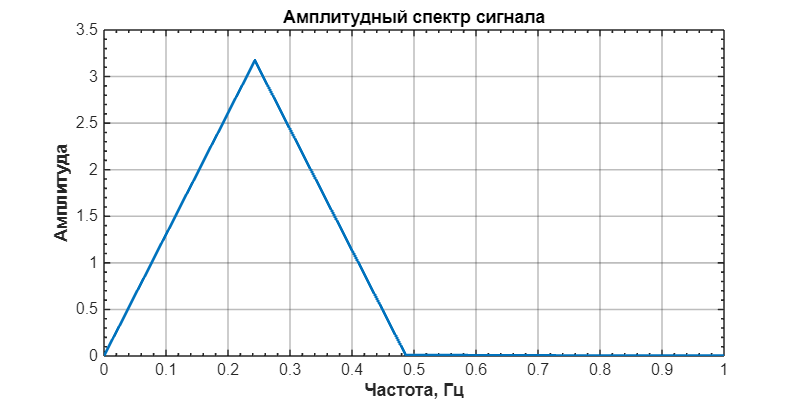

% Преобразование Фурье
Fs = 1/dt;
N = length(t);
f = (0:N-1)*(Fs/N);

fftAll = fft(alpha/160);
amp = abs(fftAll)/N;


f_plot = f(1:floor(N/2));
amp_plot = amp(1:floor(N/2)); % <-- правильно
figure('Color','w', 'Position',[100 100 800 400]);  % белый фон и размер

plot(f_plot, amp_plot, 'LineWidth', 2);             % более жирная линия
xlim([0 1]);                                       % ограничение по частоте

grid on;

% Подписи осей
xlabel('Частота, Гц', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Амплитуда', 'FontSize', 12, 'FontWeight', 'bold');

% Заголовок
title('Амплитудный спектр сигнала', 'FontSize', 14);
% Стилизация осей
set(gca, ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'Box', 'on', ...
    'GridAlpha', 0.3, ...
    'XMinorTick', 'on', ...
    'YMinorTick', 'on');

saveas(gcf, 'S-curve-fourier.png');        % PNG

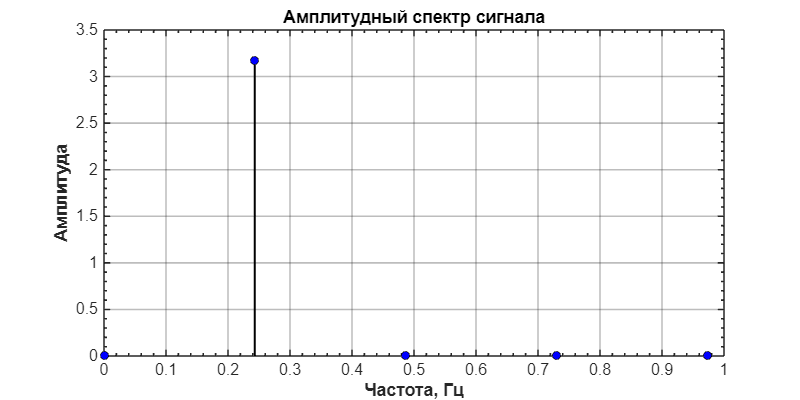

% Преобразование Фурье
Fs = 1/dt;
N = length(t);
f = (0:N-1)*(Fs/N);

fftAll = fft(alpha/160);
amp = abs(fftAll)/N;

f_plot = f(1:floor(N/2));
amp_plot = amp(1:floor(N/2));

figure('Color','w', 'Position',[100 100 800 400]);

% --- Спектр в виде линий с кружками ---
% Для каждой точки рисуем линию от (f, 0) до (f, amp) и ставим кружок

hold on;
for k = 1:length(f_plot)
    plot([f_plot(k) f_plot(k)], [0 amp_plot(k)], 'k', 'LineWidth', 1.5); % вертикальная линия
end
plot(f_plot, amp_plot, 'o', ...
    'MarkerFaceColor', 'b', ...
    'MarkerEdgeColor', 'k', ...
    'MarkerSize', 6);

xlim([0 1]);
grid on;

xlabel('Частота, Гц', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Амплитуда', 'FontSize', 12, 'FontWeight', 'bold');
title('Амплитудный спектр сигнала', 'FontSize', 14);

set(gca, ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'Box', 'on', ...
    'GridAlpha', 0.3, ...
    'XMinorTick', 'on', ...
    'YMinorTick', 'on');

hold off;

T = 4.1;
f = 1/T

f = 0.2439

dt = 0.01

dt = 0.0100

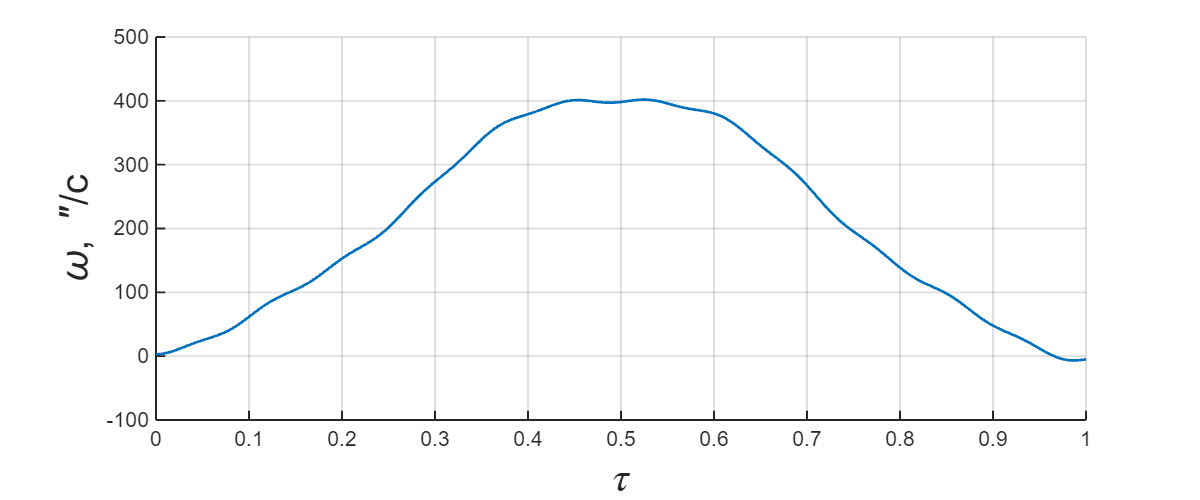

t = 0:0.01:4.1;


main_harm = cos(2*pi*f*t+pi);
harm1 = cos(2*pi*t*f*4+pi)*0.05;
harm2 = cos(2*pi*t*3+pi)*0.015;
harm3 = cos(2*pi*t*f/2)*0.03;
% Генерация шумового сигнала (равномерный или нормальный шум)
noise_amplitude = 10;  % амплитуда шума
noise = noise_amplitude * randn(size(t)); % нормальный шум (Gaussian)
y = main_harm+harm1+harm2+harm3;
y = y*200+210;

dy_dt = diff(y) / dt; 
acc = movmean(dy_dt, 25);
t_diff = t(1:end-1);
t = linspace(0,1,length(y));



figure('Position', [100 100 1200 500]);  % Широкое окно
plot(t, y,'LineWidth', 2);





% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
xlabel('$\tau$','Interpreter','latex','FontSize',30)
ylabel('\omega, ″/с', 'FontSize',30);
print(gcf, '../img/oz-gyro-sin-vel.png', '-dpng', '-r600')

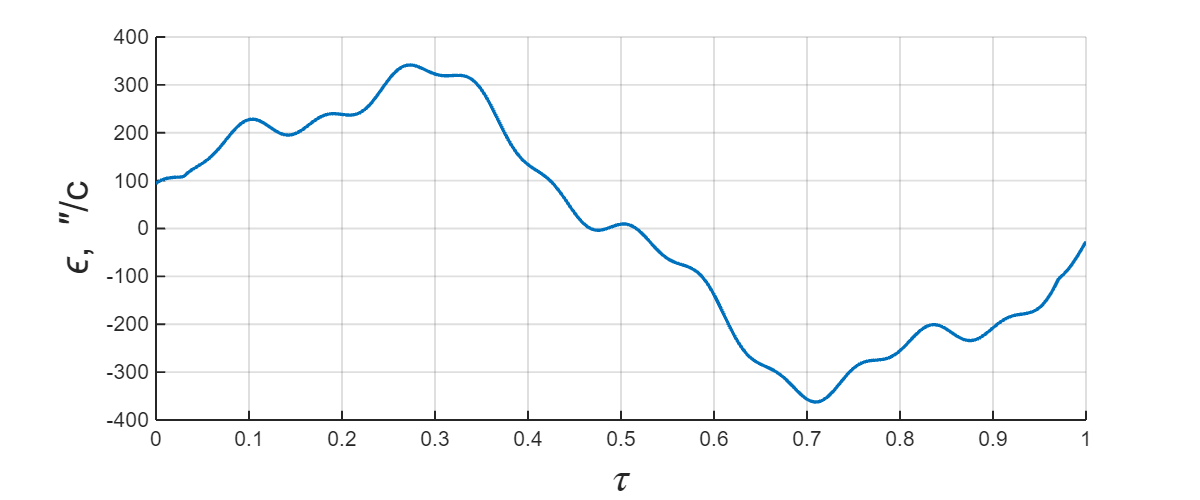



figure('Position', [100 100 1200 500]);  % Широкое окно
t = linspace(0,1,length(acc));
plot(t, acc, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»


%title('Ускорение колебаний платформы при повороте ОМС (Ось Z)', 'FontSize',20);

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
xlabel('$\tau$','Interpreter','latex','FontSize',30)
ylabel('\epsilon, ″/с', 'FontSize',30);
print(gcf, '../img/oz-gyro-sin-acc.png', '-dpng', '-r600')

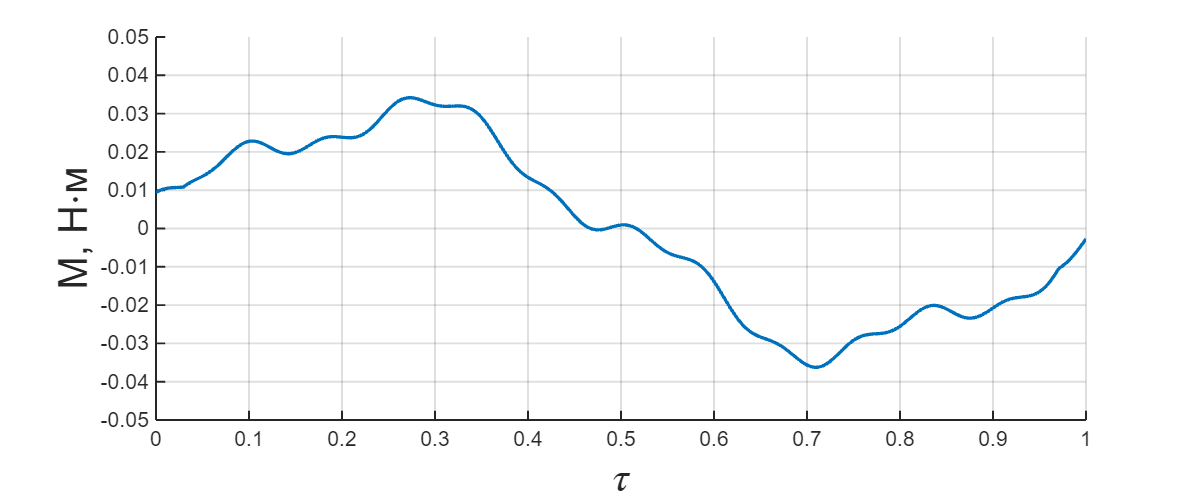


figure('Position', [100 100 1200 500]);  % Широкое окно
z_mom = acc/50*0.005;
t = linspace(0,1,length(z_mom));
plot(t, z_mom, ...
    'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);
grid on


%title('Некомпенсированный момент при повороте ОМС (Ось Z)', ...
%      'FontSize',20, 'FontWeight','bold');

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
% Задаём пределы оси Y
ylim([-0.05 0.05]);

% Задаём шаг сетки по Y
ax.YTick = -0.05 : 0.01 : 0.05;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
xlabel('$\tau$','Interpreter','latex','FontSize',30)
ylabel('М, Н⋅м', 'FontSize',25 );
print(gcf, '../img/oz-gyro-sin-mom.png', '-dpng', '-r600')

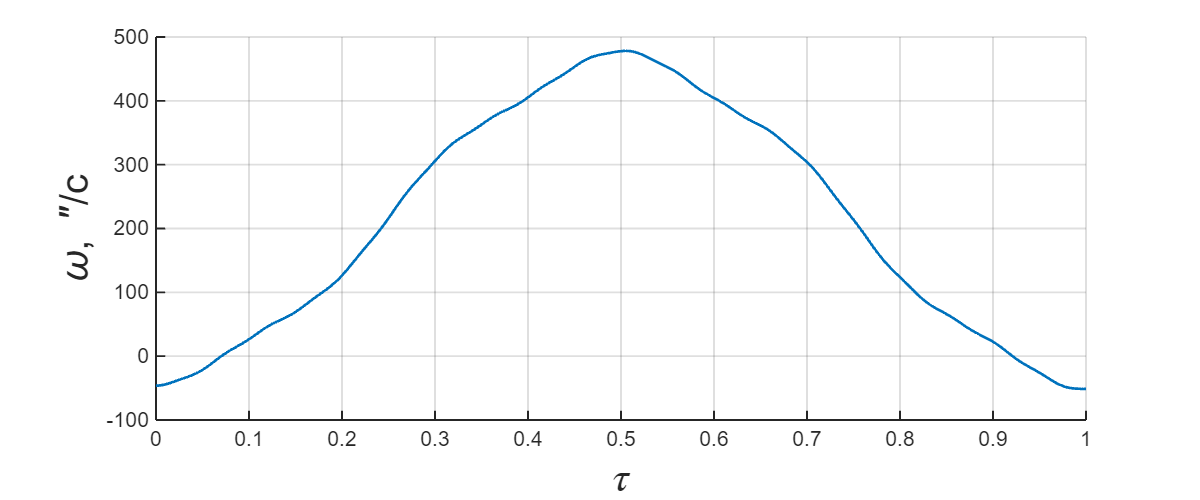

t = 0:0.01:4.1;

main_harm = cos(2*pi*f*t+pi);
harm1 = cos(2*pi*t*f*5+pi)*0.05;
harm2 = cos(2*pi*t*5+pi)*0.005;
harm3 = cos(2*pi*t*f/4)*0.03;
% Генерация шумового сигнала (равномерный или нормальный шум)
noise_amplitude = 10;  % амплитуда шума
noise = noise_amplitude * randn(size(t)); % нормальный шум (Gaussian)
y = main_harm+harm1+harm2+harm3;
y = y*250+210;

dy_dt = diff(y) / dt; 
acc = movmean(dy_dt, 45);
t_diff = t(1:end-1);
figure('Position', [100 100 1200 500]);  % Широкое окно
tau = linspace(0,1,length(y));
plot(tau, y,'LineWidth', 2);



%title('Скорость колебаний платформы при повороте ОМС (Ось Y)', ...
%      'FontSize',20, 'FontWeight','bold');

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
xlabel('$\tau$','Interpreter','latex','FontSize',30)
ylabel('\omega, ″/с', 'FontSize',30);
print(gcf, '../img/oy-gyro-sin-vel.png', '-dpng', '-r600')
grid on

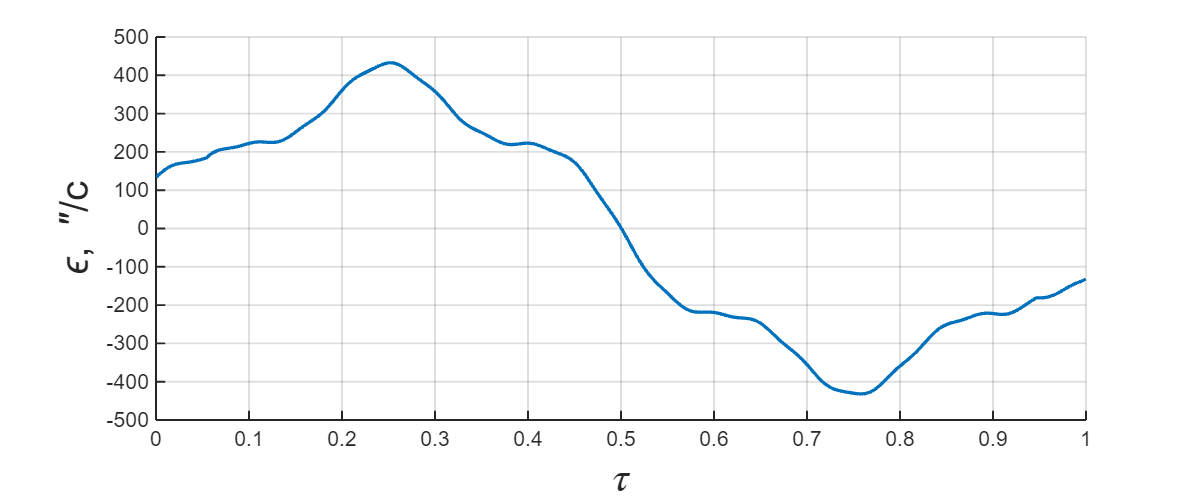


figure('Position', [100 100 1200 500]);  % Широкое окно
tau = linspace(0,1,length(acc));
plot(tau, acc, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»


%title('Ускорение колебаний платформы при повороте ОМС (Ось Y)', 'FontSize',20);

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.YTick = -500 : 100 : 500;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
xlabel('$\tau$','Interpreter','latex','FontSize',30)
ylabel('\epsilon, ″/с', 'FontSize',30);
print(gcf, '../img/oy-gyro-sin-acc.png', '-dpng', '-r600')

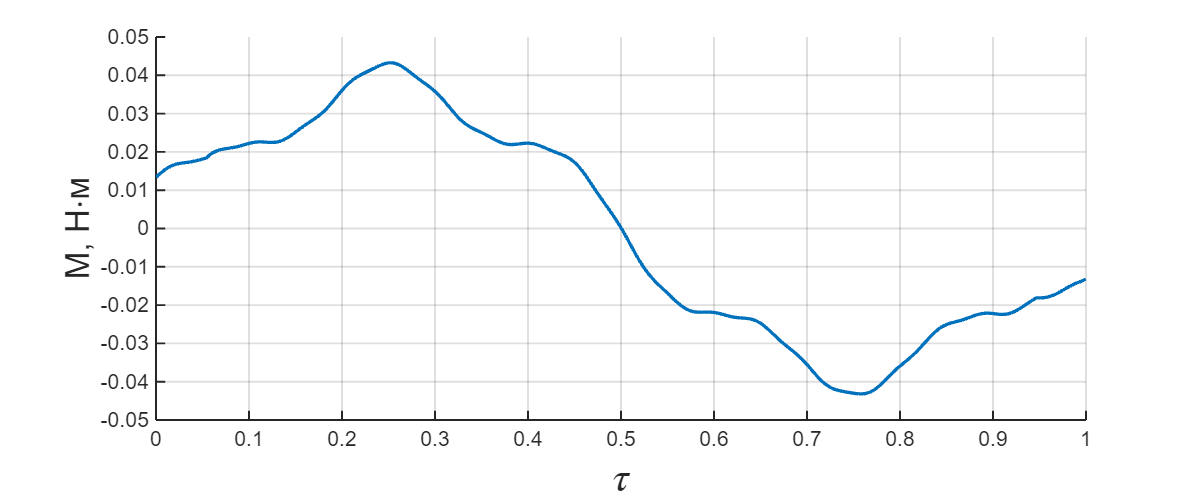


figure('Position', [100 100 1200 500]);  % Широкое окно
z_mom = acc/50*0.005;
plot(tau, z_mom, ...
    'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);
grid on


%title('Некомпенсированный момент при повороте ОМС (Ось Y)', ...
%      'FontSize',20, 'FontWeight','bold');

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
% Задаём пределы оси Y
ylim([-0.05 0.05]);

% Задаём шаг сетки по Y
ax.YTick = -0.05 : 0.01 : 0.05;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
xlabel('$\tau$','Interpreter','latex','FontSize',30)
ylabel('М, Н⋅м', 'FontSize',25);
print(gcf, '../img/oy-gyro-sin-mom.png', '-dpng', '-r600')

tt = accY.x;

Unable to resolve the name 'accY.x'.

harm3 = cos(2*pi*tt*5)*20;
aY = accY.y+harm3;
figure('Position', [100 100 800 500]);  % Широкое окно
plot(accY.x, aY, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»

xlabel('Время, с',        'FontSize',12);
ylabel('\epsilon, ″/с', 'FontSize',12);
title('Ускорение колебаний платформы при повороте ОМС (Ось Y)', 'FontSize',20);
xlim([0 4.1])
% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;

ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
exportgraphics(gcf, 'Y_acc.png', 'Resolution',300);
y_int = cumtrapz(accY.x, accY.y)-50;


figure('Position', [100 100 800 500]);  % Широкое окно
plot(tt,y_int, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»

xlabel('Время, с',        'FontSize',12);
ylabel('\omega, ″/с', 'FontSize',12);
title('Ускорение колебаний платформы при повороте ОМС (Ось Y)', 'FontSize',20);
xlim([0 4])
% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;

ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
exportgraphics(gcf, 'Y_vel.png', 'Resolution',300);

M_y = accY.y/70*0.005;
figure('Position', [100 100 800 500]);  % Широкое окно
plot(tt,M_y, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»

xlabel('Время, с',        'FontSize',12);
ylabel('М, Н⋅м', 'FontSize',12);
title('Некомпенсированный момент при повороте ОМС (Ось Y)', 'FontSize',20);
xlim([0 4])
% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.YTick = -0.07 : 0.01 : 0.08;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
exportgraphics(gcf, 'Y_mom.png', 'Resolution',300);